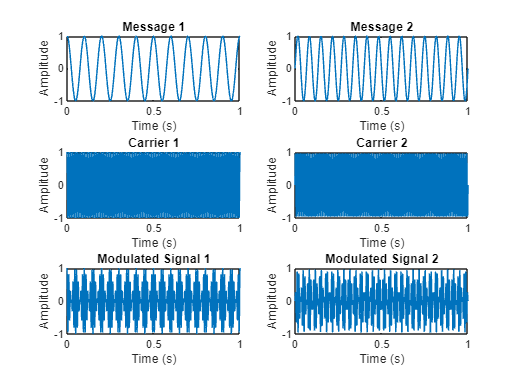

% Given parameters
fm = 10; % Hz
fm1 = 15; % Hz
fs = 1000; % Hz
fc = 100; % Hz

% Define time vector
t = 0:1/fs:1;

% Define message 1 as cos(2*pi*fm*t) and plot
message1 = cos(2*pi*fm*t);
subplot(3, 2, 1);
plot(t, message1);
title('Message 1');
xlabel('Time (s)');
ylabel('Amplitude');

% Define message 2 as sin(2*pi*fm1*t) and plot
message2 = sin(2*pi*fm1*t);
subplot(3, 2, 2);
plot(t, message2);
title('Message 2');
xlabel('Time (s)');
ylabel('Amplitude');

% Take carrier 1 as cos(2*pi*fc*t) and plot
carrier1 = cos(2*pi*fc*t);
subplot(3, 2, 3);
plot(t, carrier1);
title('Carrier 1');
xlabel('Time (s)');
ylabel('Amplitude');

% Take carrier 2 as sin(2*pi*fc*t) and plot
carrier2 = sin(2*pi*fc*t);
subplot(3, 2, 4);
plot(t, carrier2);
title('Carrier 2');
xlabel('Time (s)');
ylabel('Amplitude');

% Perform AM modulation of the both signals by multiplying the both messages with its respective carrier
modulated_signal1 = message1 .* carrier1;
modulated_signal2 = message2 .* carrier2;

% Plot modulated signals
subplot(3, 2, 5);
plot(t, modulated_signal1);
title('Modulated Signal 1');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3, 2, 6);
plot(t, modulated_signal2);
title('Modulated Signal 2');
xlabel('Time (s)');
ylabel('Amplitude');

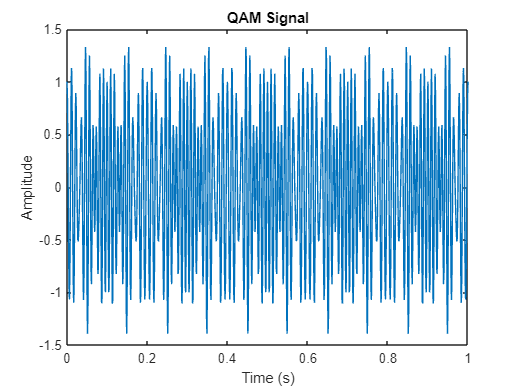

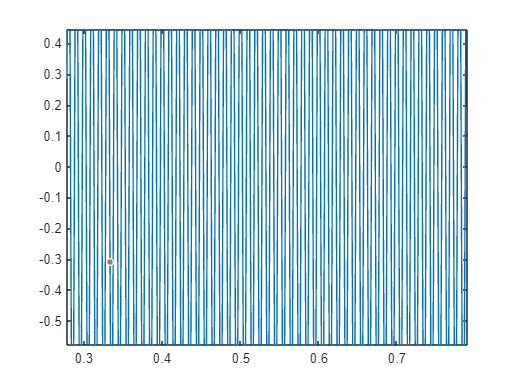


% Add both modulated signals for QAM
qam_signal = modulated_signal1 + modulated_signal2;

% Plot the result of QAM modulation
figure;
plot(t, qam_signal);
title('QAM Signal');
xlabel('Time (s)');
ylabel('Amplitude');